# Oceanographic data analysis

Is there a relationship between water salinity & water temperature? 

Can you predict the water temperature based on salinity?

#### Data loading

% Importing data samples from files
load('bottle.mat');
tbl(1:8,:) % Temperature (in Celcius), Water salinity (g/L)

ans =    10.5000   33.4400
   10.4600   33.4400
   10.4600   33.4370
   10.4500   33.4200
   10.4500   33.4210
   10.4500   33.4310
   10.4500   33.4400
   10.2400   33.4240


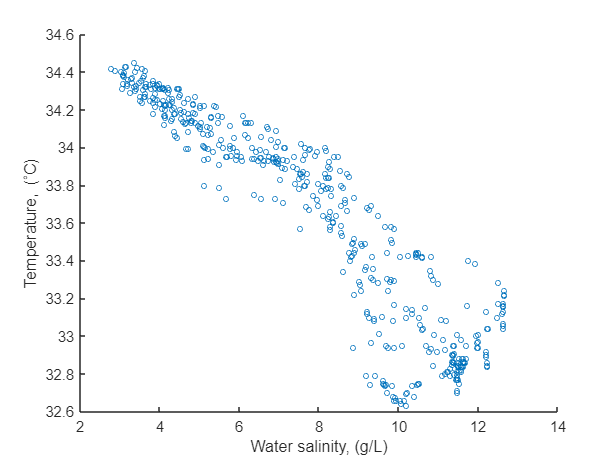

x = tbl(:,1);
y = tbl(:,2);
figure,
scatter(x, y, 12) % for illustration purpose
xlabel('Water salinity, (g/L)')
ylabel('Temperature, (^{\circ}C)')

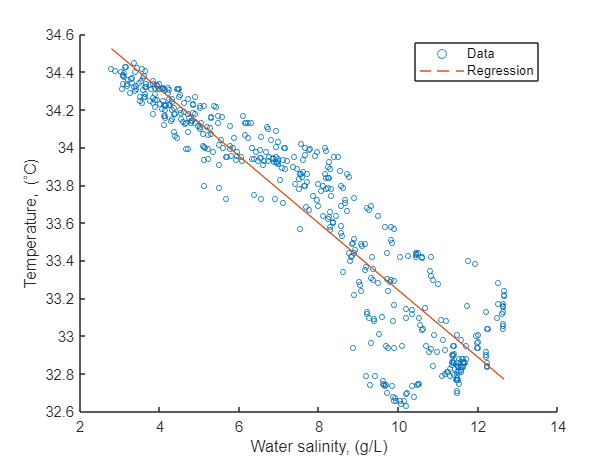

X = [ones(length(x),1) x];
% find b s.t. the linear regression relation y = b1 * x + b2
b = X\y;
y_pred = X*b; % predicted values
figure,
hold on
scatter(x, y, 12)
plot(x,y_pred,'--')
legend('Data','Regression','Location','best');
xlabel('Water salinity, (g/L)')
ylabel('Temperature, (^{\circ}C)')
hold off